# Molecular Spectroscopy of Iodine Vapor: 

# Part 1, Absorption Spectrum

First, perform the data collection tasks described in the lab manual. For the absorption spectroscopy data, prepare files as follows:

- *Full absorbance sepctrum*: A .txt file containing the full spectrum with column 1 labeled **Wavelength** and column 2 labeled as **Abs**.

- *Absorbance Peaks*: A .txt file containing the peak assignments with with column 1 labeled **Wavelength** and column 2 labeled as **Abs**, and column 3 labeled **v_excited** (make assignments of the vibrational quantum number for the excited state.

## Set up the Import Options and import the data: Part 1

The code for importing the files was auto-generated by matlab using the Home -> Import Data -> Generate Code function, and then customized by Dr. Haas for you.

You will need to modify the code below to import the specific files you created during data collection, and specify which rows of data should be imported.

% Specify the file type and the rows that you want to import
% It is important that you adjust the row numbers to include only the useful data
% Usually, a number between 2-36 should work for the first row, 
% but check your plot after import and adjust as necessary.
input = delimitedTextImportOptions("NumVariables", 3); %Specifies 2 columns in the .txt file
input.DataLines = [3, Inf]; %the first value indicates at which row MatLab should begin reading the data
input.Delimiter = "\t"; %this specifies that you are importing data from a .txt file

% Specify column names and types
input.VariableNames = ["Wavelength", "Abs", "v_excited"];
input.VariableTypes = ["double", "double", "double"];

% Specify file level properties
input.ExtraColumnsRule = "ignore";
input.EmptyLineRule = "read";

## Absorption data import

Change the file names to match yours. Be sure each file name corresponds the the correct data. 

% Import the data for Part I, Absorption spectra peaks
% you will need to change the code below to specify your path and names of
% the variables
I2Abs_full = readtable("I2Abs_full.txt", input);
I2Abs_peaks = readtable("I2Abs_peaks.txt", input);

Abs_Wavelength = I2Abs_full.Wavelength;
Abs_Intensity = I2Abs_full.Abs;
Abs_peaks = I2Abs_peaks.Wavelength; %Defines a vector of peak wavelengths
v_excited = I2Abs_peaks.v_excited;
v_ex_plus1=v_excited(2:end);

### Visulalize the full spectrum 

To confirm that data was imported as expected, plot the full spectrum.

plot(Abs_Wavelength, Abs_Intensity)
title('Absorption Spectrum of Iodine Vapor (1 atm, 25 C)')
xlabel('Puppy tails')
ylabel('Baby giggles')

## Save your code and your workspace 

Hit the save button in the Live Editor toolabr to save your work.

And save your workspace using the code below.

save IodineVapor_kh

## Calculate energies of excited state vibrational levels $\Delta G_{v'}$

From the absorption spectrum, we can claucate the energy spacing in the excited state vibrational levels. Ignoring transitions from the "hot bands", each of the peaks in the absorption spectrum occurs due to excitation of an electron from the v"=0. 

There are many peaks visible in the absorption spectrum. The most intense absorption is from $\upsilon"=0$ to $\upsilon'=25$. 

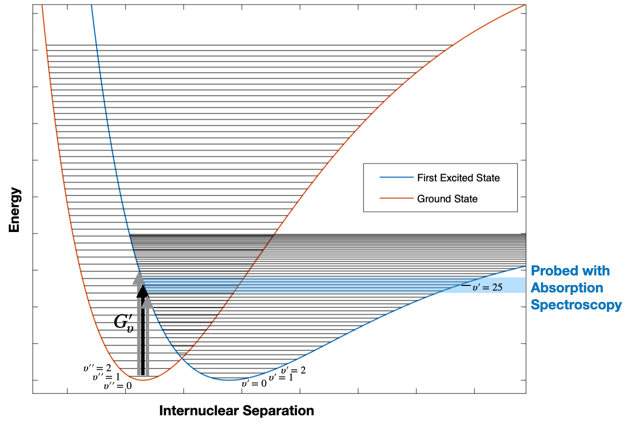

A plot of $(\upsilon + 1)$ vs $\Delta G_{\upsilon}'$ can be used to derive the ***Anharmonicity Parameter *****(**$\chi_e '$**) **and the **Harmonic Frequency (**$\omega_e'$**) of the excited state **according to the following:


$$$\Delta \mathrm{G}_{(v)}=\left|\mathrm{G}_{(v+1)}-\mathrm{G}_{(v)}\right|=\omega_{\mathrm{e}}-2 \omega_{\mathrm{e}} \chi_{\mathrm{e}}(v+1)$$$


### Calcuate $G_{\upsilon}'$ from peak wavelengths, and $\Delta G_{\upsilon}'$

Each peak in the absorption spectrum corresponds to the energy of transition $G_{\upsilon}'$.

G_ex = 1./Abs_peaks*10^7 %energies of absorption in wavenumbers (1/cm)
DeltaG_ex = diff(G_ex) %difference in adjacent G values

### Plot the data

% Fit data using fitlm (mainly for plotting)
DeltaG_ex_fit = fitlm(v_ex_plus1,DeltaG_ex,"linear");
DeltaG_ex_yfit = DeltaG_ex_fit.Coefficients.Estimate(2)*v_ex_plus1 + DeltaG_ex_fit.Coefficients.Estimate(1);

plot(v_ex_plus1,DeltaG_ex, 'o')
plot(v_ex_plus1,DeltaG_ex_yfit)
title('Spacing in enervy levels vs v')
xlabel('{Excited state vibrational quantum number}')
ylabel('')

lsq(v_ex_plus1,DeltaG_ex) %easy least squares to get errors in slope and intercept

### Trim the vectors and plot again

If necessary, remove any data points from the hot bands. One way to do this is to adjust the vectors to exclude data that is perturbed by the hot bands. 

% Trim the first 12 elements, where hot bands interfere with peak
% assignments
v_ex_trim = v_ex_plus1(13:end) ;
DeltaG_ex_trim = DeltaG_ex(13:end);
% Fit data using fitlm
DeltaG_ex_trim_fit = fitlm(v_ex_trim,DeltaG_ex_trim,"linear");
DeltaG_ex_trim_yfit = DeltaG_ex_trim_fit.Coefficients.Estimate(2)*v_ex_trim + DeltaG_ex_trim_fit.Coefficients.Estimate(1);

figure
hold on
plot(v_ex_trim,DeltaG_ex_trim, 'o')
plot(v_ex_trim,DeltaG_ex_trim_yfit)
title('Spacing in enervy levels vs v')
xlabel('{Excited state vibrational quantum number}')
ylabel('')
hold off
lsq(v_ex_trim,DeltaG_ex_trim)

### Enter Values for Slope and Intercept

Assign values to the molecular parameters

%...Based on the output above, assign values below
slope_ex = ;
slope_ex_er = ;
intercept_ex = ;
intercept_ex_err = ;

### Calculate Parameters for the Excited State:

#### Harmonic Frequency of the excited state, $\omega_e'$

- $\omega_e'$ = intercept 

- $\Delta \omega_e'$= error in intercept

omega_excited = intercept_ex %in cm^-1

omega_excited =        133.84

omega_excited_err = intercept_ex_err %in cm^-1

omega_excited_err =        1.9966

#### Anharmonicity Parameter of the excited state, $\chi_e'$

- $ -2\omega_e \chi_e$ = slope, $\chi = \frac{slope}{-2 \omega_e'}$

- 
$$$\Delta \chi_e^{\prime}=\chi_e^{\prime} \sqrt{\left(\frac{\Delta \omega_e^{\prime}}{\omega_e^{\prime}}\right)^2+\left(\frac{\Delta \text { slope }}{\text { slope }}\right)^2}$$$


chi_exicted = slope_ex/(-2*omega_excited) %unitless

chi_exicted =     0.0077903

chi_excited_err = chi_exicted*sqrt((omega_excited_err/omega_excited)^2 + (slope_ex_er/slope_ex)^2)

chi_excited_err =    0.00025682

#### Dissociation energy of the excited state, $D_e'$


$$D_e'=\frac{\omega_e'}{4\chi_e'}$$



$$$\Delta D_e^{\prime}=D_e^{\prime} \sqrt{\left(\frac{\Delta \omega_e^{\prime}}{\omega_e^{\prime}}\right)^2+\left(\frac{\Delta \chi_e'}{\chi_e'}\right)^2}$$$


D_ex = omega_excited/(4*chi_exicted) %in cm^-1

D_ex =        4295.1

D_ex_err = D_ex*sqrt((omega_excited_err/omega_excited)^2+(chi_excited_err/chi_exicted)^2)

D_ex_err =        155.42

#### Morse Parameter of the excited state, $a'$

$$a^{\prime}=\sqrt{\frac{8 \pi^2 c \mu \omega_e^{\prime} \chi_e^{\prime}}{h}}$$ , and $$\mu=\frac{m_1 m_2}{m_1+m_2}$$ where $m_1$ and $m_2$ are the masses of the atoms (use iodine average atomic mass).


$$$\Delta a^{\prime}=\sqrt{\left(\frac{\partial a^{\prime}}{\partial \omega_e^{\prime}}\right)^2\left(\Delta \omega_e^{\prime}\right)^2+\left(\frac{\partial a^{\prime}}{\partial \chi_e^{\prime}}\right)^2\left(\Delta \chi_e^{\prime}\right)^2}$$$


***Watch Units!!***

I_amu = 126.9045; %atomic mass of iodine atom in g/mol
    avagadro = 6.022137e23; %avagadro's number molecules per mole
    I_g = ; %convert to g for one atom
    I_kg = ; %convert to kg for one atom
mu = I_kg^2/(I_kg+I_kg)

mu =    1.0537e-25

c = ; %speed of light in cm/sec
h = 6.626E-34; %Planc's constant in kg*m^2 / sec
a_ex = sqrt(8*pi^2*c*mu*omega_excited*chi_exicted/h)/(10^10) % in 1/m converted to 1/Angstroms

a_ex =        1.9784

%a_ex_err = %watch units!

## Save your code and your workspace 

Hit the save button in the Live Editor toolabr to save your work.

And save your workspace using the code below.